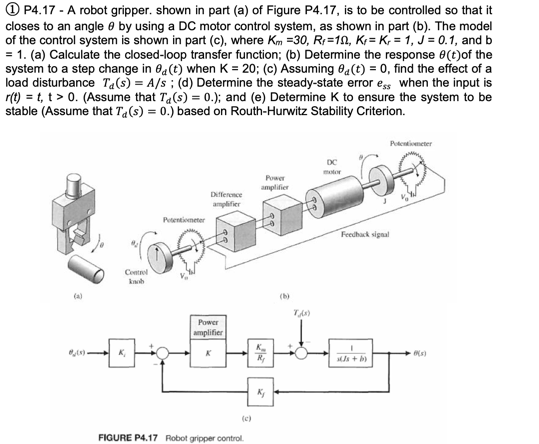

clc; clear; close all;

%%givens
Km = 30;
Rf = 1;
Kr = 1;
Kf = 1;
J  = 0.1;
b  = 1;

s = tf("s");

%%G(s)
G_base = (Km/Rf) * 1/(s*(J*s + b));
%G(s) = K * G_base

disp("Open-loop forward path without K:")

Open-loop forward path without K:


G_base

G_base =
 
      30
  -----------
  0.1 s^2 + s
 
Continuous-time transfer function.
Model Properties



%% (a)closed-loop transfer function (symbolic in K)
syms K_sym s_sym A

T_sym = (300*K_sym) / (s_sym^2 + 10*s_sym + 300*K_sym);
disp("a) Closed-loop transfer function theta/theta_d =")

a) Closed-loop transfer function theta/theta_d =


T_sym

$$T\_sym = \frac{300\,K_{\mathrm{sym}}}{{s_{\mathrm{sym}}}^{2}+10\,s_{\mathrm{sym}}+300\,K_{\mathrm{sym}}}$$


%% (b)Step response for K = 20
K = 20;

G = K * G_base;
T = feedback(G, 1);

disp("(b) Closed-loop transfer function for K = 20:")

(b) Closed-loop transfer function for K = 20:


T

T =
 
         600
  -----------------
  0.1 s^2 + s + 600
 
Continuous-time transfer function.
Model Properties


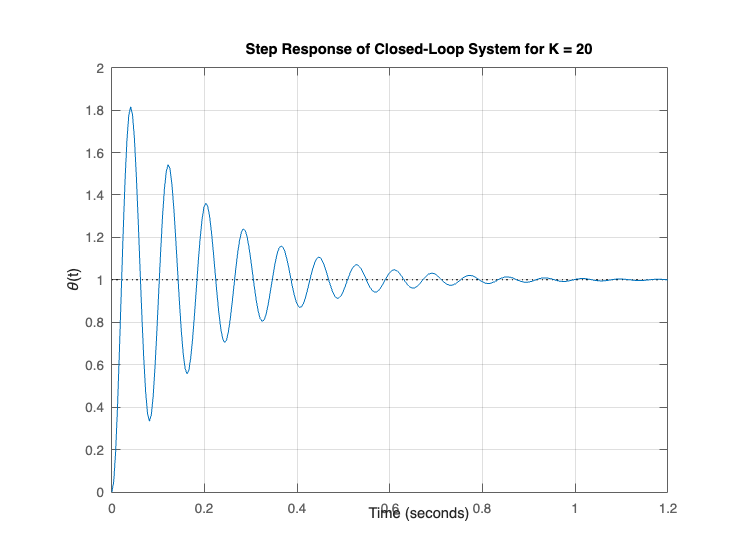


figure;
step(T);
grid on;
title("Step Response of Closed-Loop System for K = 20");
ylabel("\theta(t)");


info = stepinfo(T);
disp("Step response data:")

Step response data:


disp(info)

         RiseTime: 0.0141
    TransientTime: 0.7759
     SettlingTime: 0.7759
      SettlingMin: 0.3340
      SettlingMax: 1.8161
        Overshoot: 81.6087
       Undershoot: 0
             Peak: 1.8161
         PeakTime: 0.0406



Numerator:


     0     0   600



Denominator:


    0.1000    1.0000  600.0000



Analytical unit-step response theta(t):


$$theta\_t = 1-{\mathrm{e}}^{-5\,t}\,\left(\cos\left(5\,\sqrt{239}\,t\right)+\frac{\sqrt{239}\,\sin\left(5\,\sqrt{239}\,t\right)}{239}\right)$$


%% (c) Disturbance response theta/Td with theta_d = 0
% Disturbance Td enters additively before the mechanical plant:
% theta = P(s) * [ (Km/Rf)K * e + Td ], with e = -theta since theta_d = 0
% Therefore: theta/Td = P / (1 + (Km/Rf)K P)

P = 1/(s*(J*s + b));          % mechanical plant only
Td_to_theta = feedback(P, K*(Km/Rf));   % = P/(1 + K*(Km/Rf)*P)

disp('(c) Transfer function from disturbance Td to output theta:')

(c) Transfer function from disturbance Td to output theta:


Td_to_theta

Td_to_theta =
 
          1
  -----------------
  0.1 s^2 + s + 600
 
Continuous-time transfer function.
Model Properties


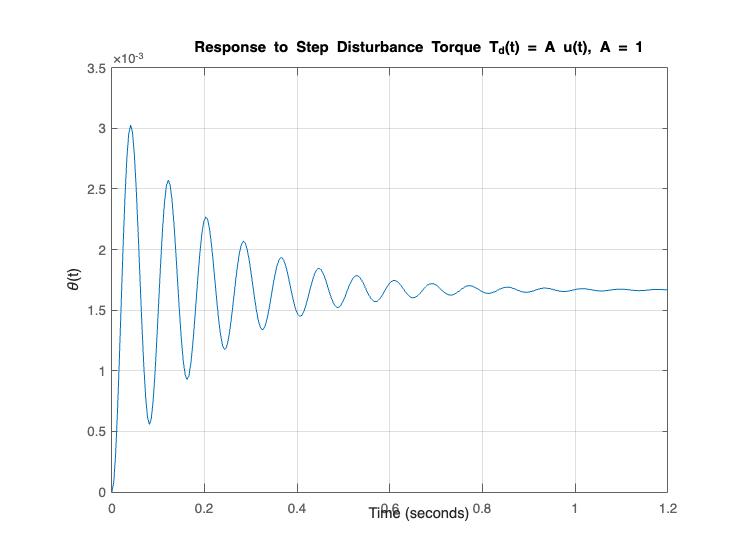


% Example: step disturbance Td(t) = A u(t), take A = 1
A_val = 1;

figure;
step(A_val * Td_to_theta);
grid on;
title('Response to Step Disturbance Torque T_d(t) = A u(t), A = 1');
ylabel('\theta(t)');


% Steady-state value due to step disturbance
theta_ss_dist = dcgain(A_val * Td_to_theta);
fprintf('(c) Steady-state output due to step disturbance A = 1: %.6f\n', theta_ss_dist);

(c) Steady-state output due to step disturbance A = 1: 0.001667


fprintf('(c) General result: theta(inf) = A/(30K) = %.6f * A\n\n', 1/(30*K));

(c) General result: theta(inf) = A/(30K) = 0.001667 * A





%% (d) Steady-state error for ramp input r(t) = t, t > 0, with Td = 0
% For unity feedback, E/R = 1/(1+G)
E_over_R = 1/(1 + G);

disp('(d) Error transfer function E(s)/R(s):')

(d) Error transfer function E(s)/R(s):


E_over_R

E_over_R =
 
     0.1 s^2 + s
  -----------------
  0.1 s^2 + s + 600
 
Continuous-time transfer function.
Model Properties



% Ramp input: R(s) = 1/s^2
R_ramp = 1/s^2;
E_ramp = minreal(E_over_R * R_ramp);

% Final Value Theorem: ess = lim_{t->inf} e(t) = lim_{s->0} s E(s)
% For a type-1 system, ess = 1/Kv where Kv = lim_{s->0} sG(s)
Kv_sys = minreal(s * G);
Kv = dcgain(Kv_sys);

ess_ramp = 1 / Kv;

fprintf('(d) Velocity error constant Kv = %.6f\n', Kv);

(d) Velocity error constant Kv = 600.000000


fprintf('(d) Steady-state error for unit ramp input r(t)=t: ess = %.6f\n', ess_ramp);

(d) Steady-state error for unit ramp input r(t)=t: ess = 0.001667


fprintf('(d) General result: ess = 1/(30K)\n\n');

(d) General result: ess = 1/(30K)





%% (e) Stability condition on K using Routh-Hurwitz
% Closed-loop denominator:
% 0.1 s^2 + s + 30K = 0
% or equivalently s^2 + 10s + 300K = 0
%
% For a 2nd-order polynomial a2 s^2 + a1 s + a0,
% Routh-Hurwitz requires: a2 > 0, a1 > 0, a0 > 0
% Here: a2 = 1, a1 = 10, a0 = 300K
% So stability requires K > 0

fprintf('(e) Closed-loop characteristic polynomial: s^2 + 10 s + 300 K\n');

(e) Closed-loop characteristic polynomial: s^2 + 10 s + 300 K


fprintf('(e) By Routh-Hurwitz, the system is stable for: K > 0\n');

(e) By Routh-Hurwitz, the system is stable for: K > 0


fprintf('(e) K = 0 gives a pole at the origin, so it is marginally stable, not asymptotically stable.\n\n');

(e) K = 0 gives a pole at the origin, so it is marginally stable, not asymptotically stable.





%% Optional: verify poles numerically for the chosen K = 20
disp('Closed-loop poles for K = 20:')

Closed-loop poles for K = 20:


poles_T = pole(T)

poles_T =   -5.0000 +77.2981i
  -5.0000 -77.2981i



fprintf('Is the system stable for K = 20? %d\n', isstable(T));

Is the system stable for K = 20? 1
